m = master;


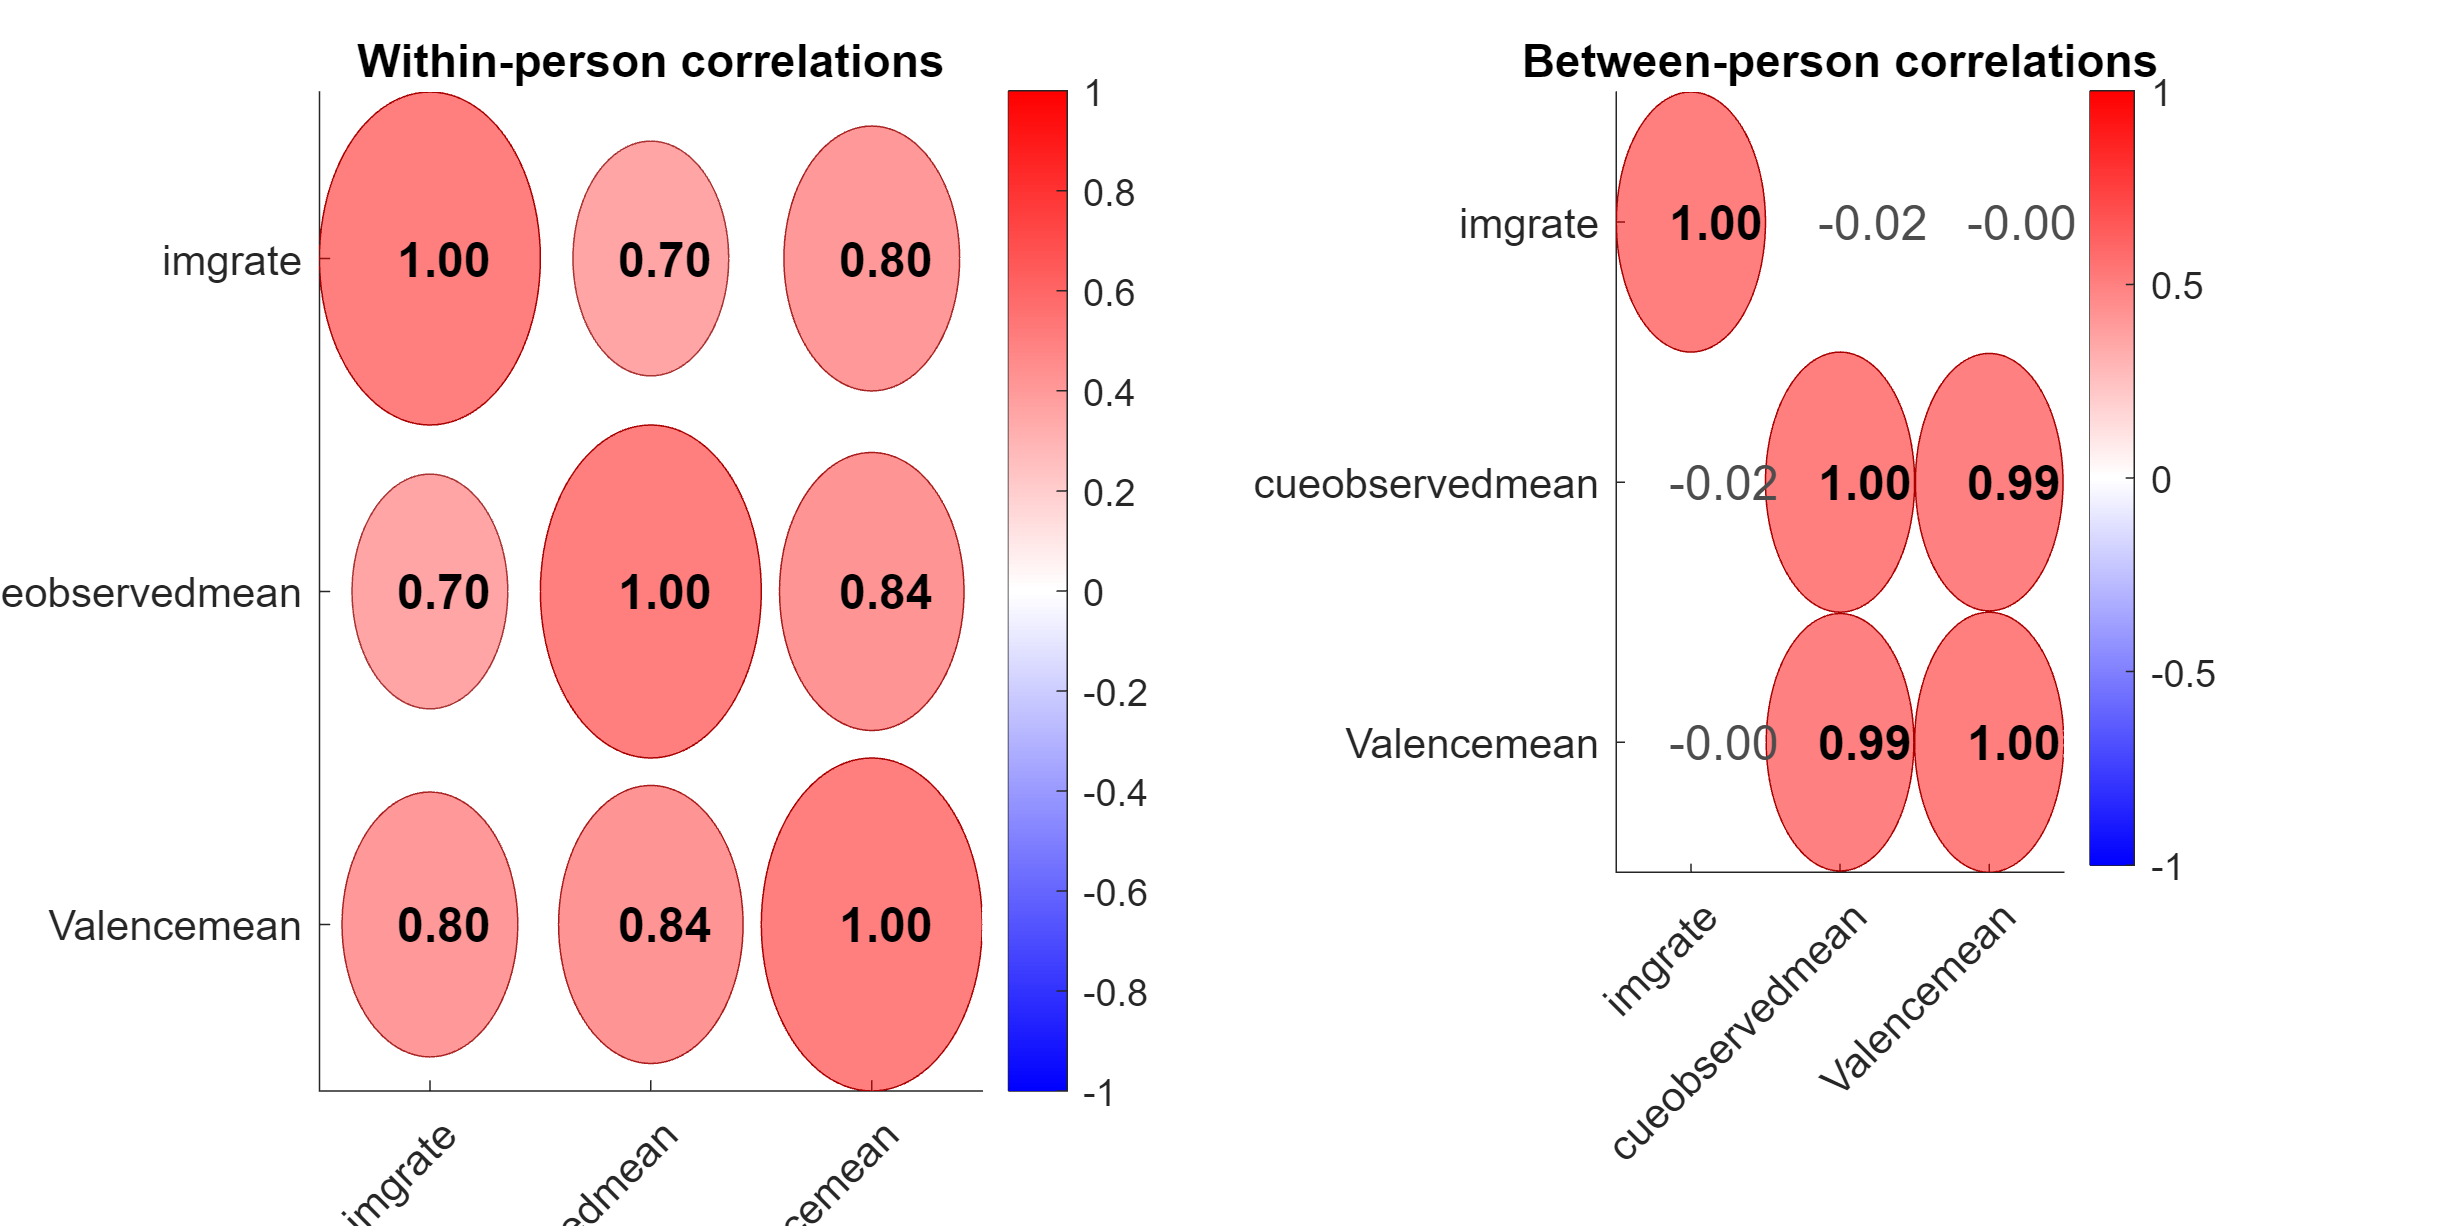

data_table_obj = m;
varnames = {'img_rate', 'cue_observed_mean', 'Valence_mean'};
groupvarname = 'subj';
% Calculate and plot a series of within-person and between-person correlation matrices, with full and partial correlations
%
% Inputs:
% data_table_obj:   Matlab table object with variable names in column properties
%                   NaN is missing data
% varnames:         Cell string of variable names to intercorrelate {'name1 'name2' 'etc'}
% groupvarname:     Name of grouping variable, usually participant ID
%                   must have numeric integer codes
%
% Outputs:
% R_FULL            Structure of correlation values and statistics
%                   see ttest3d for explanation of all variables
%
% %*Documentation not done yet -- please help update me!*
% Tor Wager, 5/2023
%
% %*Optional inputs and flags not implemented yet -- please update me!*
% % e.g., optional flag to suppress plots, suppress partial correlations
% % control for obligatory covariates in all analyses using partialcorr
% 
% *Updates needed to:*
% - Use Fisher Z-transform in stats in 3dttest, preserving correlation
% values as output in plots
% - Optionally print correlation tables -- see correlation_to_text(OUT.r, OUT.sig);
%

dopartial = false;

% Get data matrix from table
datmatrix = [];
for i = 1:length(varnames), datmatrix(:, i) = data_table_obj.(varnames{i}); end

% Get grouping variable from table
G = [];
G = data_table_obj.(groupvarname);

% remove NaNs casewise

[wasnan, datmatrix] = nanremove(datmatrix);
G(wasnan) = [];

% Get unique levels of grouping var
Gu = unique(G);
nlevels = length(Gu);
nvars = size(datmatrix, 2);

% Find correlations within each grouping unit, means between
% -------------------------------------------------------------------
r_matrix = NaN .* zeros(nvars, nvars, nlevels);
meandata = NaN .* zeros(nlevels, nvars);

for i = 1:length(Gu)

    dat_i = datmatrix(G == Gu(i), :);

    r_matrix(:, :, i) = corr(dat_i);

    if dopartial
        rp_matrix(:, :, i) = partialcorr(dat_i);
    end

    % means for between-person correlations
    meandata(i, :) = mean(dat_i, 1);

end

R_FULL = ttest3d(r_matrix);
R_FULL.var_names = varnames;
R_FULL.between_r_matrix = corr(meandata);

create_figure('r', 1, 2);
plot_correlation_matrix(R_FULL, 'var_names', R_FULL.var_names, 'nofigure');
title('Within-person correlations')

subplot(1, 2, 2)
plot_correlation_matrix(meandata, 'var_names', R_FULL.var_names, 'nofigure');
title('Between-person correlations')



if dopartial
    R_PARTIAL = ttest3d(rp_matrix);
    R_PARTIAL.var_names = varnames;
    R_PARTIAL.between_r_matrix = partialcorr(meandata);

    create_figure('r_partial', 1, 2);
    plot_correlation_matrix(R_PARTIAL, 'var_names', R_PARTIAL.var_names, 'nofigure');
    title('Within-person partial correlations')

    subplot(1, 2, 2)
    plot_correlation_matrix(R_PARTIAL.between_r_matrix, 'var_names', R_PARTIAL.var_names, 'nofigure');
    title('Between-person partial correlations')

end
